% Mining the relationship between demographic and fitting result
% First extract 2 tables: FitTable & DemographicTable
run;
temp = readtable('data/demographic.csv', 'ReadVariableNames', true, 'ReadRowNames', true );


## study of relationship between significant mobility levels and population density.


% consistent with FitTable
DemographicTable = temp(:,:);
DemographicTable.pop_density = log(DemographicTable.pop_density);
DemographicTable.top_density = log(DemographicTable.top_density);
DemographicTable.population = log(DemographicTable.population);


[B, Info] = lasso(DemographicTable{:,1:end-1}, exp(FitTable.Intercept), 'CV', 10, 'Lambda', 0.01); %, 'Lambda', 0.012
Coeff = B(:, Info.IndexMinMSE);
idx = Coeff ~= 0;
names = DemographicTable.Properties.VariableNames(1:end-1);
names(idx)

ans = 1×7 cell array
    {'top_density'}    {'Children0_18'}    {'Adults35_54'}    {'high_risk_fraction'}    {'HispanicOrLatino'}    {'AsianAlone'}    {'AmericanIndianOrAlaskaNative'}


preds = Coeff' * DemographicTable{:,1:end-1}' + Info.Intercept(Info.IndexMinMSE);
Info.LambdaMinMSE

ans = 0.0100

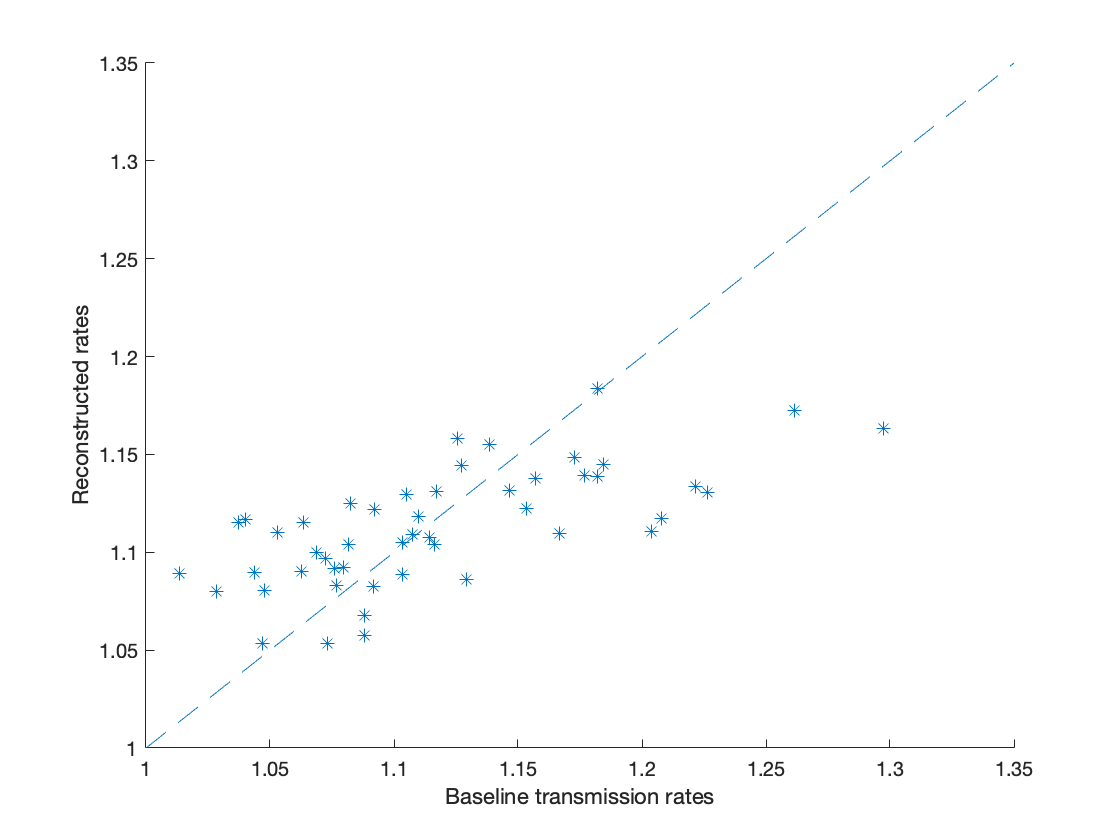

figure;
scatter(exp(FitTable.Intercept),preds, '*');
xlim([1 1.35])
ylim([1 1.35])
hold on
plot([1 1.35],[1 1.35],'--', 'Color',[0, 0.4470, 0.7410])
xlabel('Baseline transmission rates')
ylabel('Reconstructed rates')

## Study of regression intercept via census data.

%title('Baseline transmission rates reconstruction from demographic info')

temp = DemographicTable{:,1:end-1};
idx(1) = 0;
mdl = fitlm(temp(:,idx),exp(FitTable.Intercept))

mdl = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7

Estimated Coefficients:
                   Estimate       SE         tStat      pValue  
                   ________    _________    _______    _________

    (Intercept)      1.0781      0.30996     3.4783    0.0011681
    x1              0.01253    0.0060168     2.0824     0.043286
    x2             -0.60879      0.38718    -1.5724       0.1232
    x3              0.79759      0.93881    0.84958      0.40027
    x4             -0.32548      0.23256    -1.3996      0.16881
    x5              0.18884     0.085009     2.2214      0.03164
    x6             0.099706      0.15245    0.65403      0.51657
    x7             -0.16191      0.14628 

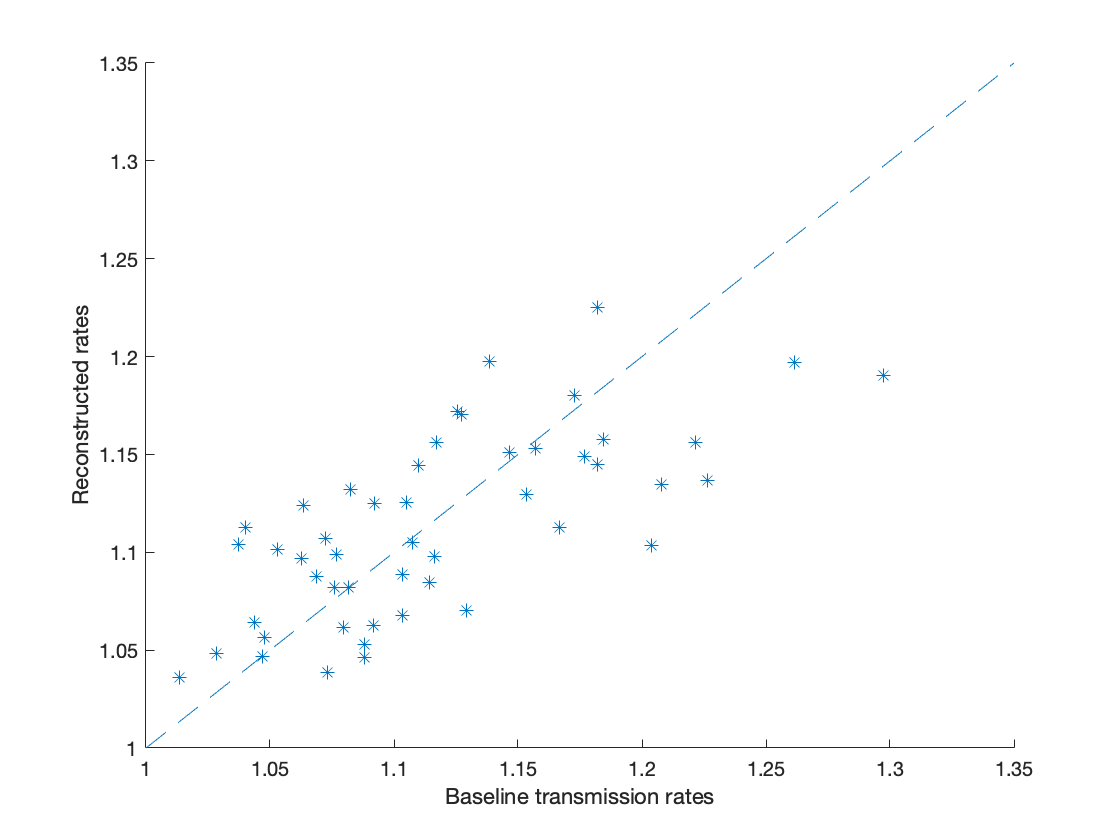

preds = predict(mdl, temp(:,idx));
figure;
scatter(exp(FitTable.Intercept),preds, '*');
xlim([1 1.35])
ylim([1 1.35])
hold on
plot([1 1.35],[1 1.35],'--', 'Color',[0, 0.4470, 0.7410])
xlabel('Baseline transmission rates')
ylabel('Reconstructed rates')